% Lecture 12 

addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Root Finding'))

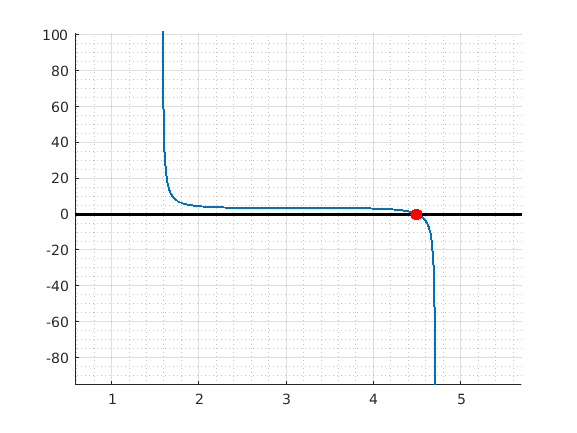

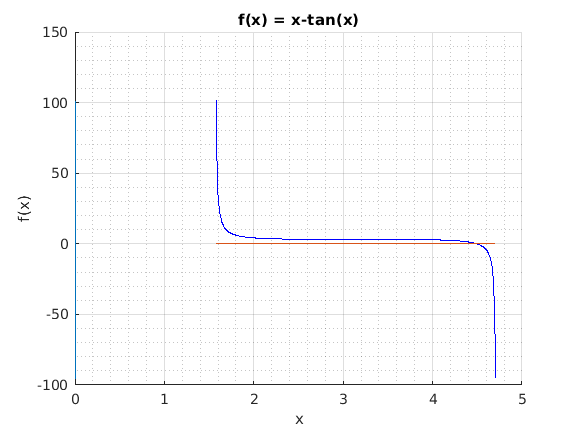

f = @(x) x - tan(x);
plotRoot(f, pi/2 + 0.01, 3*pi/2 - 0.01)

Now going to to the estimation with Newton

root seems about 4.5 from diagram

f = @(x) x - tan(x);
dfdx = @(x) 1 - (sec(x)).^2;

newtonRoot(f, dfdx, 4, 10)

n = 100, solution = 3628179375799372847994010046689260806413195363221504.00000000000


ans = 'No Answer'

%need to makesure value of f' is not 0 near x0
% since that will take estimate of root very far (inf)

**NOTE: that 5e-7 is the same as 0.5e-6 (to 6 decimals)**

newtonRoot(f, dfdx, 4.5, 6)

n = 3, solution = 4.493409


ans =    4.493409457909247


%need to makesure value of f' is not 0 near x0
% since that will take estimate of root very far (inf)